# Example 1.3: Pdf and Cdf of a Discrete RV

Note: this script reproduces Example 1.3 (Section 1.2.2) of **Statistics for Chemical Engineers**: a discrete RV with domain {-1, 0, 1, 2}. Victor Z UW-Madison, 2020 pdf and cdf of a simple discrete RV

clc; clear all; close all hidden;

## Pdf

Note: f(x) is the probability of each value; f(0) = 0.4 and f(1) = 0.6. pdf

x=[-1 0 1 2];
f=[0 0.4 0.6 0];
n=length(x);

## Cdf from the pdf

Note: F(x) adds the pdf over all values less than or equal to x. compute cdf using pdf

t = linspace(-1,2);
for i=1:length(t)
    F(i)=0;
    for j=1:length(x)
    F(i)=F(i)+(x(j)<=t(i))*f(j);
    end
end

## Plot the pdf

Note: the pdf has points of mass at the domain values. visualize pdf

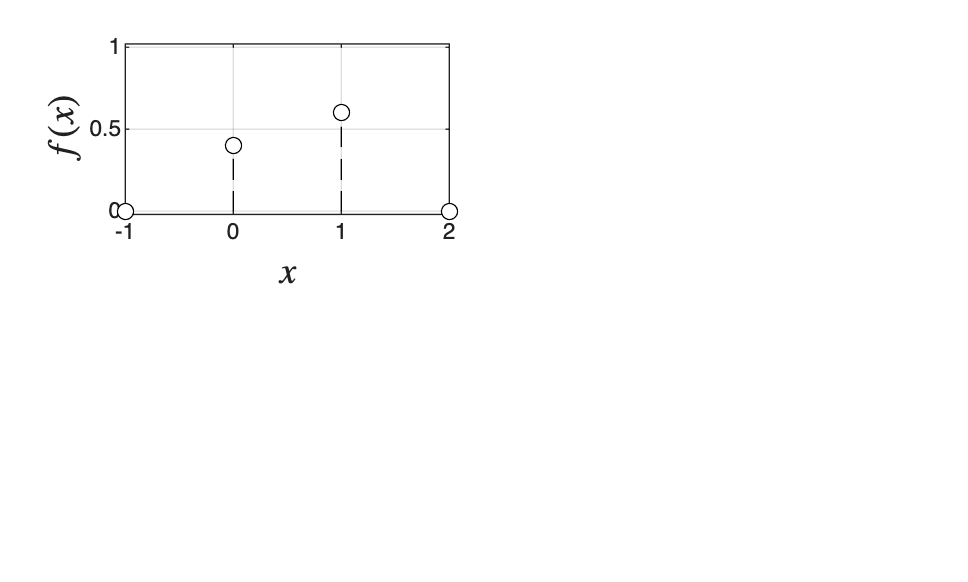

figure(1)
subplot(2,2,1)
plot(0*ones(100,1),linspace(0,f(2),100),'black--')
hold on
plot(1*ones(100,1),linspace(0,f(3),100),'black--')
hold on
scatter(x,f,'MarkerFaceColor','w','MarkerEdgeColor','black')
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
axis([-1 2 -0.02 1.02])

## Plot the cdf

Note: the cdf has a staircase form, with jumps at the points of mass. visualize cdf

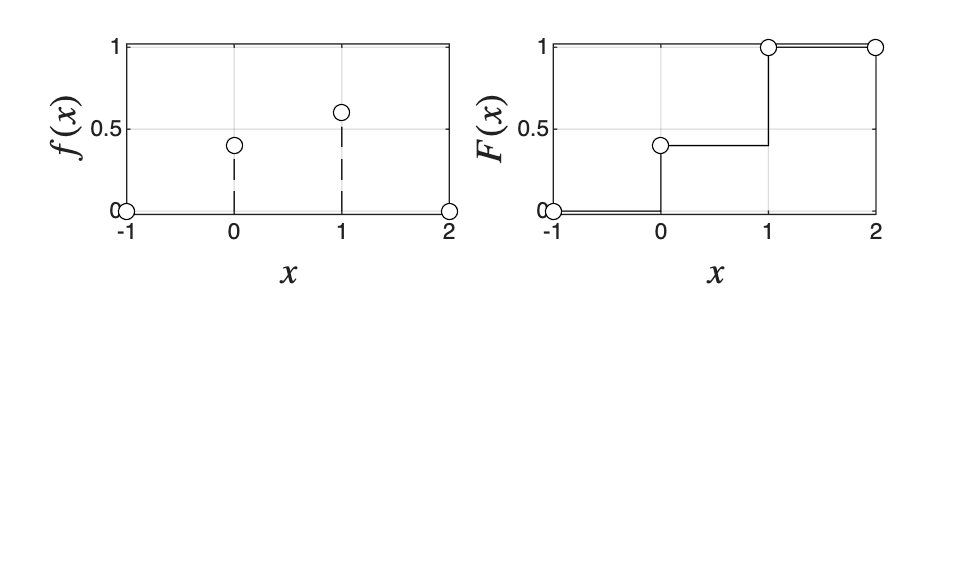

subplot(2,2,2)
stairs(t,F,'black-')
hold on
for j=1:n
    scatter(x(j),interp1(t,F,x(j),'nearest'),'MarkerFaceColor','w','MarkerEdgeColor','black')
    hold on
end
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
axis([-1 2 -0.02 1.02])

print -depsc ch1_pdfcdfdiscrete.eps

## Note

The cdf values match the fraction of outcomes below each threshold, e.g. F(0) = 0.4 and F(1) = 1.